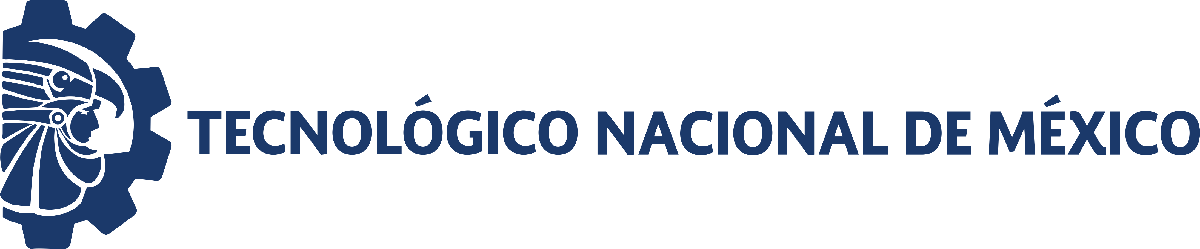                                 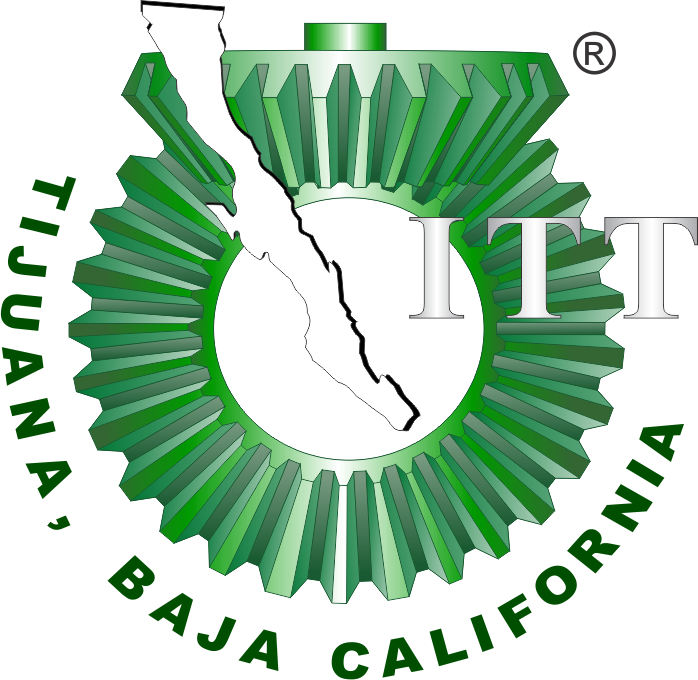

# Práctica 5: Regeneración de glóbulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

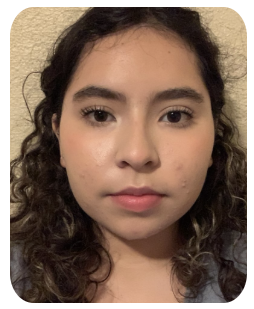

Nombre del alumno: **Urbina Gómez Eliza Yasunari**

Número de control: **22211768**

Correo institucional: **l22211768@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')
tend = 180; %Tiempo de la simulación en días 
dt = 1E-3; %Intervalo de integración para el método de solución por diferencias finitas 
n = round (tend/dt); %Cantidad de iteraciones para el método númerico 

%Condiciones inciales base para cada paciente 
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parámetros particulares para cada paciente 
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057]

gamma =     0.7690
    0.3880
    0.5100
    0.5900
    0.2620
    0.3240
    0.3560
    0.0890
    0.2430
    0.0570


beta =  [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22211768 %Semilla para asegurar reproducibilidad

seed = 22211768

rng(seed, 'twister')
%Intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente 
x1_0 = x1_0*interval; disp('x1(0) = ');disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = ');disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = ');disp(x3_0');

x1(0) = 
   59.1164   58.6495   58.8914   58.8251   59.4753   59.4380   58.8329   59.4010   58.7771   58.6815



x2(0) = 
   44.0868   43.7386   43.9190   43.8696   44.3545   44.3266   43.8753   44.2990   43.8337   43.7625



x3(0) = 
  886.7461  879.7421  883.3707  882.3764  892.1302  891.5701  882.4928  891.0143  881.6559  880.2221



## Caso: Sin transfusión sanguínea [u(t) = 0]

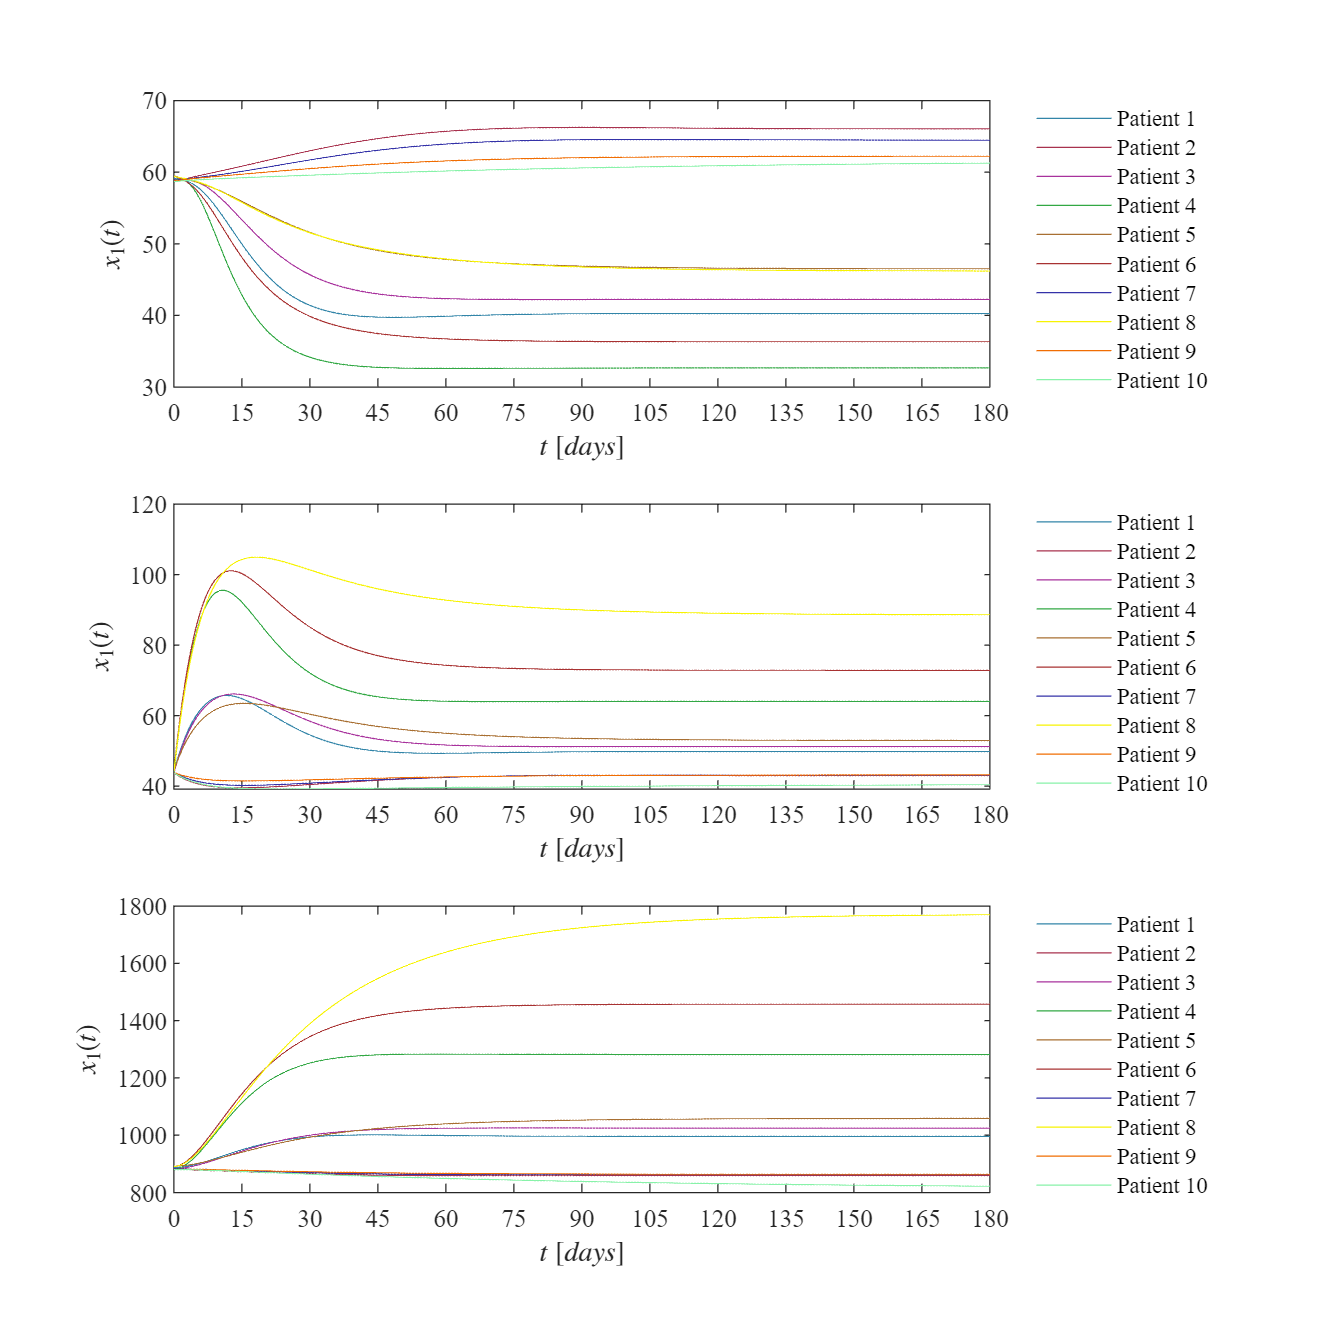

u = zeros(n+1,1); %No hay transfusion
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Con transfusión sanguínea [u(t) = 1]

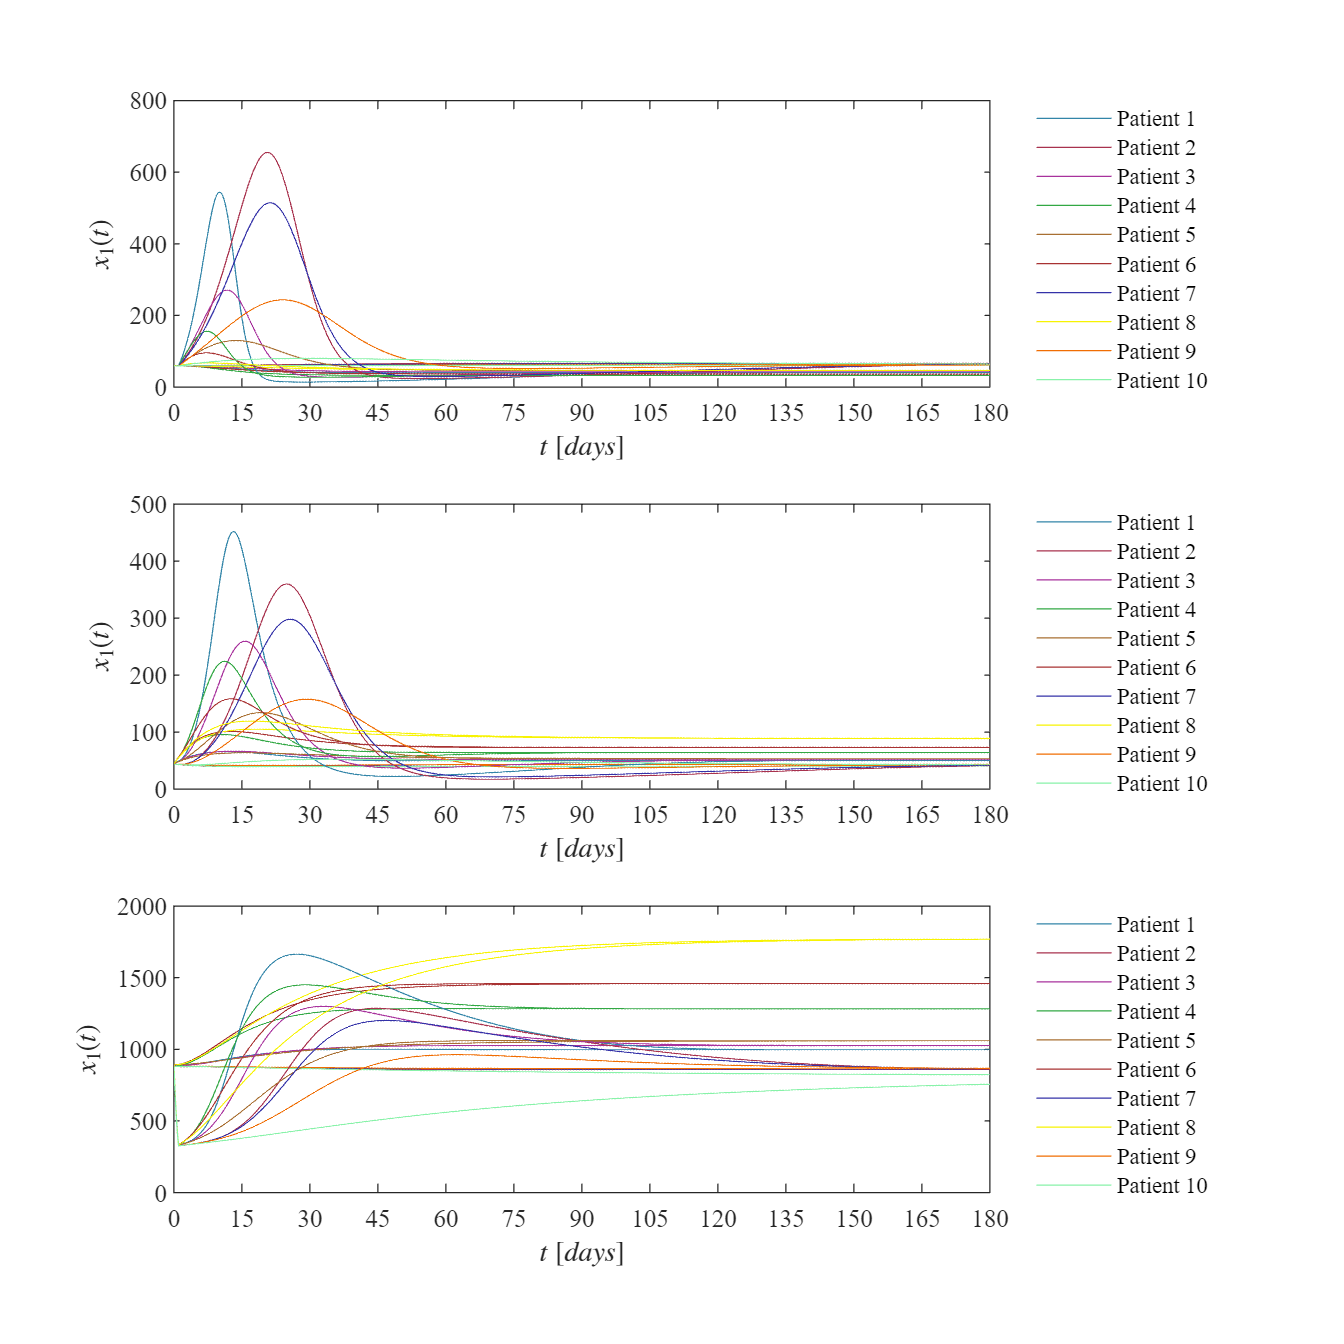

u = zeros(size(t));
for k = 1:length(t)
    if t(k)>= 0
        if t(k) <=1
            u(k) =1;
        end
    end
end
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Función: Modelo matemático

 
$${\overset{\ldotp }{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$${\overset{\ldotp }{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\overset{\ldotp }{x} }_3 =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3]=system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%Parámetros fijos del sistema 
Base = 885.42; X0 = 7.3785; k1 = 0.125; k2= 0.1667; alpha = 0.00833;
t = (0:dt:tend)';
n = round(tend/dt);
x1 = zeros(n+1,1); x1(1) = x1_0;
x2 = zeros(n+1,1); x2(1) = x2_0;
x3 = zeros(n+1,1); x3(1) = x3_0;
    for i = 1:n %Método de Euler (diferencias finitas)
        x1(i+1) = x1(i) + (beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1-u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end 

## Función: Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
set(figure(fig),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,20,20])
    mycolors = [50, 133, 168;
        168, 50, 78;
        168, 50, 157;
        50, 168, 68;
        168, 111, 50;
        168, 50, 50;
        52, 50, 168;
        247, 243, 2;
        240, 109, 2;
        136, 242, 169]/255;

subplot(3,1,1)
hold on; grid off; box on;colororder(mycolors)
plot(t,x1)
xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
ylabel ('$x_1(t)$','Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)
L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca,'FontName','Times New Roman','FontSize',10) 

subplot(3,1,2)
hold on; grid off; box on;colororder(mycolors)
plot(t,x2)
xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
ylabel ('$x_1(t)$','Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)
L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca,'FontName','Times New Roman','FontSize',10)

subplot(3,1,3)
hold on; grid off; box on;colororder(mycolors)
plot(t,x3)
xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
ylabel ('$x_1(t)$','Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)
L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca,'FontName','Times New Roman','FontSize',10)

if fig == 1
    exportgraphics(gcf,'Caso sin transfusion.pdf','ContentType','Vector')
elseif fig == 2
     exportgraphics(gcf,'Caso con transfusion.pdf','ContentType','Vector')
end
end